## How to Manipulate a Faust

This livescript is intended to gently introduce the operations available to manipulate a Faust object. It comes after the first livescript (available [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.mlx) for download or [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.html) as a web page), so it's assumed you already know how to create a Faust object from one way or another.

Keep in mind that a full API doc is available [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/namespacematfaust.html) every time you need details. In particular the Faust class is documented [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html).

**NOTE**: the livescript is made to be executed sequentially, otherwise, skipping some cells, you would end up on an import error.

### Table of Contents:

1. Getting Basic Information about a Faust Object

1.1 Obtaining Dimension and Scalar Type Information

1.2 Obtaining Other Faust Specific Information

1.3 Plotting a Faust

1.4 About Sparsity!

2. Faust Algebra and other Operations

2.1 Transpose, conjugate, transconjugate

2.2 Add, Subtract and Multiply

2.3 Faust Multiplication by a Vector or a Matrix

2.4 Faust Norms

2.5 Faust Normalizations

2.6 Faust Concatenation

2.7 Faust Indexing and Slicing

### 1. Getting Basic Information about a Faust Object

First of all, given any object, you might ask yourself if it's a Faust or not (typically when you receive an object in a function, matlab being built on dynamic types, you can't say for sure it's a Faust). [Faust.isFaust()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#ac5d5fbe66ef212a1c7043b78504f87fc) is the function to verify an object is a Faust. Its use is straighforward as you can see in the documentation. Note by the way, that a more accessible alias is available at the package root `(matfaust.isFaust`).

### 1.1 Obtaining Dimension and Scalar Type Information

Firstly, let's list basic Faust informative methods/attributes you're probably used to for matlab matrices:

- [size](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7146c7de95b35efc570a377765edda27),

- [numel](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#af62f554cd8b491a2c75ee06019f87d8a),

- [isreal](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7527e1fda21bc1678646a4b40db28eb6).

To keep it really clear, let's show some examples operated on a random Faust.

F = matfaust.rand(5,10)

F = Faust size 5x10, density 3.1, nnz_sum 155, 5 factor(s): 
- FACTOR 0 (real) SPARSE, size 5x8, density 0.625, nnz 25
- FACTOR 1 (real) SPARSE, size 8x8, density 0.625, nnz 40
- FACTOR 2 (real) SPARSE, size 8x5, density 1, nnz 40
- FACTOR 3 (real) SPARSE, size 5x5, density 1, nnz 25
- FACTOR 4 (real) SPARSE, size 5x10, density 0.5, nnz 25

size(F)

ans =      5    10


numel(F)

ans = 50

isreal(F)

ans = logical
   1


If the attributes printed out above seem not clear to you, you're probably not a Matlab user. Anyway you'll find all descriptive informations in the FAµST API documentation (see the links above).

As a complement, you can also refer to the Matlab API documentation:

- [size](https://www.mathworks.com/help/matlab/ref/size.html)

- [numel](https://www.mathworks.com/help/matlab/ref/numel.html)

- [isreal](https://www.mathworks.com/help/matlab/ref/isreal.html)

About size, it's noteworthy that contrary to what Matlab is capable of on an array, you cannot [reshape](https://www.mathworks.com/help/matlab/ref/reshape.html) a Faust.

### 1.2 Obtaining Other Faust Specific Information

As you've seen in this livescript and the first one, when you print a Faust object, several pieces of information appear. Most of them are also available independently with specific functions.

For instance, if you want information about factors, nothing is more simple than calling directly the next functions:

- [numfactors()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a5e77419460592366457aa60175472e2e) ; which gives you the number of factors (aka layers) a Faust object is composed of.

- [factors()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a65a84416b4b1fd050654a02232e95d2f) ; which allows you to copy any of the Faust's factors givens its index.

Going back to our F object, let's call these functions:

numfactors(F)

ans = 5

For example, try to copy the third factor:

f3 = factors(F, 3)

f3 =    (1,1)       0.6747
   (2,1)       0.1861
   (3,1)       0.3943
   (4,1)       0.9627
   (5,1)       0.8914
   (6,1)       0.9190
   (7,1)       0.3666
   (8,1)       0.6478
   (1,2)       0.9990
   (2,2)       0.5762
   (3,2)       0.7183
   (4,2)       0.9727
   (5,2)       0.1263
   (6,2)       0.2359
   (7,2)       0.6577
   (8,2)       0.9747
   (1,3)       0.4491
   (2,3)       0.2179
   (3,3)       0.9607
   (4,3)       0.2979
   (5,3)       0.6902
   (6,3)       0.4500
   (7,3)       0.9129
   (8,3)       0.2257
   (1,4)       0.7983
   (2,4)       0.3299
   (3,4)       0.3559
   (4,4)       0.8236
   (5,4)       0.1541
   (6,4)       0.4884
   (7,4)       0.0303
   (8,4)       0.1343
   (1,5)       0.5932
   (2,5)       0.4671
   (3,5)       0.0055
   (4,5)       0.0170
   (5,5)       0.5230
   (6,5)       0.1512
   (7,5)       0.9959
   (8,5)       0.1423


Note that, since Faust 2.3, the function doesn't alterate the factor format. If the Faust object contains a sparse factor then you'll receive a sparse matrix.

Since Faust 2.3 again, it's possible to retrieve a sub-sequence of Faust factors.

Go straight to the example, extracting factors from F:

factors(F, 3:4)

ans = Faust size 8x5, density 1.625, nnz_sum 65, 2 factor(s): 
- FACTOR 0 (real) SPARSE, size 8x5, density 1, nnz 40
- FACTOR 1 (real) SPARSE, size 5x5, density 1, nnz 25

Hmm... something is different from the previous example. We indeed received a Faust as return type, great! You've just learned another way to create a Faust from another, additionally to what you've seen in the first [livescript](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_manipulation.html).

Without this function, you'd surely have written something similar to:

import matfaust.Faust
Faust({factors(F, 3), factors(F, 4)})

ans = Faust size 8x5, density 1.625, nnz_sum 65, 2 factor(s): 
- FACTOR 0 (real) SPARSE, size 8x5, density 1, nnz 40
- FACTOR 1 (real) SPARSE, size 5x5, density 1, nnz 25

OK, that's not awful but I let you imagine how much complicated it is with more factors.

### 1.3 Plotting a Faust

It's quite useful to print a `Faust` as we've seen before, calling disp(F), `display(F)` or just `F` in an interactive terminal but this is wordy.  How about plotting a Faust in a more graphical fashion ?

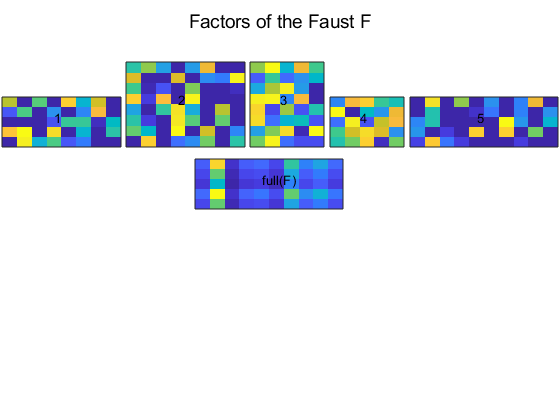

imagesc(F)

What do we see above ? On the bottom right is the dense matrix associated to F, obtained with `full(F)`. On the top are the indexed factors of F. Note that you can change the default [colormap](https://www.mathworks.com/help/matlab/ref/colormap.html) in matplotlib parameters.

Let's look at a last example:

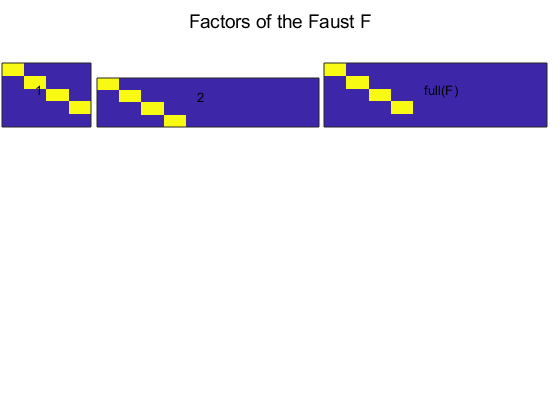

imagesc(Faust({eye(5,4),eye(4,10)}))

### 1.4 About Sparsity!

Three functions of the Faust class are here to evaluate the sparsity of a Faust object.

Let's call the first one:

nnz_sum(F)

ans = 155

I'm sure you guessed exactly what the function returns, if you doubt it, here is the doc: [Faust.nnz_sum()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7dc7f3cb86b02b3c2cd725387c34300d). The smaller `nnz_sum`, the sparser the Faust.

Next comes the function: [Faust.density()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#ac33ff53bbff16f93666acec05031511b).

This function along with its reciprocal [Faust.rcg()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#aff3261319b63c49d51a699726edc74bc) can give you a big hint on how much your Faust is potentially optimized both for storage and calculation. The sparser the Faust, the larger the Relative Complexity Gain (RCG)!

density(F)

ans = 3.1000

rcg(F)

ans = 0.3226

According to its RCG, this Faust doesn't seem to be of any help for optimization but look at the graphic the next script generates:

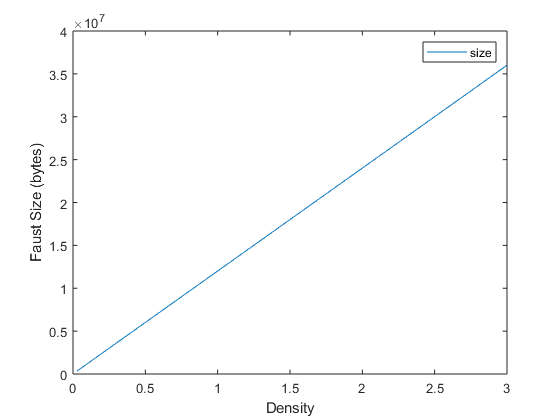

figure()
nfactors = 3;
startd = 0.01;
endd = 1;
dim_sz = 1000;
ntests = 10;
sizes = zeros(ntests, 1);
rcs = zeros(ntests, 1);
densities = linspace(startd, endd, ntests);
for i=1:ntests
   d = densities(i);
   F = matfaust.rand(dim_sz, dim_sz, 'num_factors', nfactors, 'density', d, 'fac_type', 'sparse');
   sizes(i) = nbytes(F);
   rcs(i) = density(F);
end
plot(rcs, sizes)
legend('size')
xlabel('Density')
ylabel('Faust Size (bytes)')

Isn't it obvious now that the smaller the density the better?! Indeed, for two Faust objects of the same shape and the same number of factors, a smaller density (linearly) implies a smaller file size for storage. This point applies also to the memory (RAM) space to work on a Faust.

We'll see later how the computation can benefit of a bigger RCG (or smaller density). But let's point out right now that the sparsity is often a tradeoff with accuracy, as the following plot shows about the truncated SVD of a matrix $M \in {\mathbb R}^{512 \times 512$. Note beforehand that the SVD of M (truncated or not) can be seen as a Faust which approximates M.

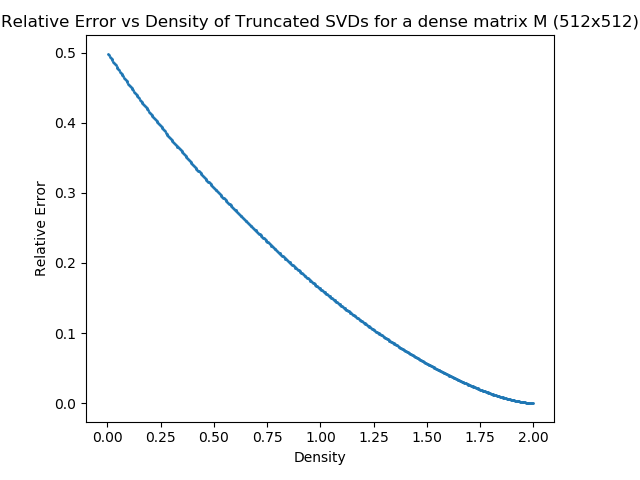

Here is the script to reproduce the last figure with pyfaust: [test_svd_rc_vs_err.py](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/test_svd_rc_vs_err.py)

### 2. Faust Algebra and other Operations

In order to write some nice algorithms using Faust objects, you'll have to use the basic "stable" operations a Faust is capable of. Let's make a tour of them.

#### 2.1 Transpose, conjugate, transconjugate

- [Faust.transpose](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a029a3db751ae1282eca2af94ce4101ec) or [.'](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a029a3db751ae1282eca2af94ce4101ec)

- [Faust.conj](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#aec9036a3d251fd47038a9a338b91502d),

- [Faust.ctranspose](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a66c1abdcbcfe8505457ce69a7b355716) or ['](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a66c1abdcbcfe8505457ce69a7b355716)

You are probably familiar with .' and ' shorthand operators from Matlab. Well, they are also used in the Faust class.

G = matfaust.rand(10, 15, 'dim_sizes', [10,15], 'field', 'complex')

G = Faust size 10x15, density 2, nnz_sum 300, 5 factor(s): 
- FACTOR 0 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 1 (complex) SPARSE, size 10x15, density 0.333333, nnz 50
- FACTOR 2 (complex) SPARSE, size 15x14, density 0.357143, nnz 75
- FACTOR 3 (complex) SPARSE, size 14x11, density 0.454545, nnz 70
- FACTOR 4 (complex) SPARSE, size 11x15, density 0.333333, nnz 55

G.'

ans = Faust size 15x10, density 2, nnz_sum 300, 5 factor(s): 
- FACTOR 0 (complex) SPARSE, size 15x11, density 0.333333, nnz 55
- FACTOR 1 (complex) SPARSE, size 11x14, density 0.454545, nnz 70
- FACTOR 2 (complex) SPARSE, size 14x15, density 0.357143, nnz 75
- FACTOR 3 (complex) SPARSE, size 15x10, density 0.333333, nnz 50
- FACTOR 4 (complex) SPARSE, size 10x10, density 0.5, nnz 50

conj(G)

ans = Faust size 10x15, density 2, nnz_sum 300, 5 factor(s): 
- FACTOR 0 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 1 (complex) SPARSE, size 10x15, density 0.333333, nnz 50
- FACTOR 2 (complex) SPARSE, size 15x14, density 0.357143, nnz 75
- FACTOR 3 (complex) SPARSE, size 14x11, density 0.454545, nnz 70
- FACTOR 4 (complex) SPARSE, size 11x15, density 0.333333, nnz 55

G'

ans = Faust size 15x10, density 2, nnz_sum 300, 5 factor(s): 
- FACTOR 0 (complex) SPARSE, size 15x11, density 0.333333, nnz 55
- FACTOR 1 (complex) SPARSE, size 11x14, density 0.454545, nnz 70
- FACTOR 2 (complex) SPARSE, size 14x15, density 0.357143, nnz 75
- FACTOR 3 (complex) SPARSE, size 15x10, density 0.333333, nnz 50
- FACTOR 4 (complex) SPARSE, size 10x10, density 0.5, nnz 50

What really matters here is that the results of G.', conj(G) and G' are all Faust objects. Behind the scene, there is just one memory zone allocated to the factors. Strictly speaking they are memory views shared between G, G.' and G'. So don't hesitate to use!

#### 2.2 Add, Subtract and Multiply

s = size(G, 1);
F = matfaust.rand(s, s);
G = matfaust.rand(s, s, 'field', 'complex');
F+G

ans = Faust size 10x10, density 5.6, nnz_sum 560, 8 factor(s): 
- FACTOR 0 (complex) SPARSE, size 10x20, density 0.1, nnz 20
- FACTOR 1 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 2 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 3 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 4 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 5 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 6 (complex) SPARSE, size 20x20, density 0.05, nnz 20
- FACTOR 7 (complex) SPARSE, size 20x10, density 0.1, nnz 20

Go ahead and verify it's accurate.

norm(full(F+G)-(full(F)+full(G)), 'fro')

ans = 0

Some points are noticeable here:

- F is real but G is complex. The Faust API is able to return the proper type for the resulting Faust, that is a complex Faust.

- F+G is composed of 8 factors, however F and G are both 5 factors long. It's due to the way the addition is implemented (Faust concatenation is hiding behind).

Subtracting is not different:

F-G

ans = Faust size 10x10, density 5.6, nnz_sum 560, 8 factor(s): 
- FACTOR 0 (complex) SPARSE, size 10x20, density 0.1, nnz 20
- FACTOR 1 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 2 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 3 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 4 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 5 (complex) SPARSE, size 20x20, density 0.25, nnz 100
- FACTOR 6 (complex) SPARSE, size 20x20, density 0.05, nnz 20
- FACTOR 7 (complex) SPARSE, size 20x10, density 0.1, nnz 20

You can also add/subtract scalars to Faust objects.

F+2

ans = Faust size 10x10, density 3.6, nnz_sum 360, 8 factor(s): 
- FACTOR 0 (real) SPARSE, size 10x20, density 0.1, nnz 20
- FACTOR 1 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 2 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 3 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 4 (real) SPARSE, size 20x11, density 0.272727, nnz 60
- FACTOR 5 (real) SPARSE, size 11x20, density 0.272727, nnz 60
- FACTOR 6 (real) SPARSE, size 20x20, density 0.05, nnz 20
- FACTOR 7 (real) SPARSE, size 20x10, density 0.1, nnz 20

Note that here again `numfactors(F+2) ~= numfactors(F)`.

The FAµST API supports equally the Faust to array addition and subtraction.

F+full(F)

ans = Faust size 10x10, density 4.5, nnz_sum 450, 8 factor(s): 
- FACTOR 0 (real) SPARSE, size 10x20, density 0.1, nnz 20
- FACTOR 1 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 2 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 3 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 4 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 5 (real) SPARSE, size 20x20, density 0.375, nnz 150
- FACTOR 6 (real) SPARSE, size 20x20, density 0.05, nnz 20
- FACTOR 7 (real) SPARSE, size 20x10, density 0.1, nnz 20

F-full(F)

ans = Faust size 10x10, density 4.5, nnz_sum 450, 8 factor(s): 
- FACTOR 0 (real) SPARSE, size 10x20, density 0.1, nnz 20
- FACTOR 1 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 2 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 3 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 4 (real) SPARSE, size 20x20, density 0.15, nnz 60
- FACTOR 5 (real) SPARSE, size 20x20, density 0.375, nnz 150
- FACTOR 6 (real) SPARSE, size 20x20, density 0.05, nnz 20
- FACTOR 7 (real) SPARSE, size 20x10, density 0.1, nnz 20

all(all(full(F-full(F)) < eps))

ans = logical
   1


Now let's multiply these Fausts!

FG = F*G

FG = Faust size 10x10, density 5, nnz_sum 500, 10 factor(s): 
- FACTOR 0 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 1 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 2 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 3 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 4 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 5 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 6 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 7 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 8 (complex) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 9 (complex) SPARSE, size 10x10, density 0.5, nnz 50

norm(full(FG)-full(F)*full(G))/norm(full(F)*full(G))

ans = 9.0087e-17

Faust scalar multiplication is also available and here again the result is a Faust object!

F*2

ans = Faust size 10x10, density 2.5, nnz_sum 250, 5 factor(s): 
- FACTOR 0 (real) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 1 (real) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 2 (real) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 3 (real) SPARSE, size 10x10, density 0.5, nnz 50
- FACTOR 4 (real) SPARSE, size 10x10, density 0.5, nnz 50

#### 2.3 Faust Multiplication by a Vector or a Matrix

When you multiply a Faust by a vector or a matrix (the number of nrows must match the number of Faust columns), you'll get respectively a vector or a matrix as result.

vec = rand(size(F, 2), 1);
F*vec

ans =    41.0501
   49.2117
   45.6702
   55.8418
   30.6538
   39.0950
   44.5995
   52.0164
   39.0722
   25.9827


Let's launch a timer to compare the execution times of Faust-vector multiplication and Faust's dense matrix-vector multiplication.

F_times_vec = @() F*vec

F_times_vec = function_handle with value:
    @()F*vec


FD = full(F);
FD_times_vec = @() FD*vec

FD_times_vec = function_handle with value:
    @()FD*vec


timeit(F_times_vec)

ans = 3.5931e-05

timeit(FD_times_vec)

ans = 7.1565e-07

all(all(F*vec-FD*vec < 1e-7))

ans = logical
   1


rcg(F)

ans = 0.4000

When the RCG is lower than 1 the Faust-vector multiplication is slower. Making a random Faust with a large RCG (small density) shows better results.

G = matfaust.rand(1024, 1024, 'num_factors', 3, 'density', .001, 'fac_type', 'sparse')

G = Faust size 1024x1024, density 0.00292969, nnz_sum 3072, 3 factor(s): 
- FACTOR 0 (real) SPARSE, size 1024x1024, density 0.000976563, nnz 1024
- FACTOR 1 (real) SPARSE, size 1024x1024, density 0.000976563, nnz 1024
- FACTOR 2 (real) SPARSE, size 1024x1024, density 0.000976563, nnz 1024

GD = full(G);
vec2 = rand(1024, 1);
timeit(@() G*vec2)

ans = 6.9531e-05

timeit(@() GD*vec2)

ans = 0.0016

rcg(G)

ans = 341.3333

It goes without saying that a big RCG gives a big speedup to the Faust-vector multiplication relatively to the corresponding (dense) matrix-vector multiplication. I hope the example above has finished to convince you.

Just to convince you as well of the Faust-vector multiplication accuracy:

norm(G*vec2 - GD*vec2)

ans = 4.5356e-16

What applies to Faust-vector multiplication remains valid about Faust-matrix multiplication. Take a look:

M = rand(1024,32);
timeit(@() G*M)

ans = 0.0038

timeit(@() GD*M)

ans = 0.0129

norm(GD*M-G*M)/norm(GD*M)

ans = 6.6552e-17

Well, what do we see? A quicker Faust-matrix multiplication than the matrix-matrix corresponding multiplication, though a good accuracy of the Faust-matrix multiplication is also clearly confirmed.

These examples are somehow theoretical because we cherry-pick the Faust to ensure that the RCG is good to accelerate the muplication, but at least it shows the potential speedup using Faust objects.

#### 2.4 Faust Norms

The Faust class provides a norm function which handles different types of norms. This function is really close to Matlab [norm](https://www.mathworks.com/help/matlab/ref/norm.htm) function.

In the following example, three of the four norms available are computed.

norm(F,1)

ans = 193.4601

norm(F, inf)

ans = 146.0016

norm(F, 'fro')

ans = 123.8180

norm(full(F), 1)

ans = 193.4601

norm(full(F), inf)

ans = 146.0016

norm(full(F), 'fro')

ans = 123.8180

Perfect! But a last norm is available, this is the Faust's 2-norm. Let's see in the next small benchmark how the Faust 2-norm is being computed faster than the Faust's dense matrix 2-norm.

timeit(@() norm(G, 2))

ans = 0.0021

timeit(@() norm(GD, 2))

ans = 1.5850

The power-iteration algorithm implemented in the FAµ?ST C++ core is faster on G and the relative error is not bad too. The norm computation is faster as it benefits from faster Faust-vector multiplication.

err = abs((norm(G, 2)-norm(GD,2))/norm(GD,2))

err = 0.0034

#### 2.5 Faust Normalizations

The FAµST API proposes a group of normalizations. They correspond to the norms available and discussed above.

It's possible to normalize along columns or rows with any type of these norms.

F = matfaust.rand(5, 10)

F = Faust size 5x10, density 3.1, nnz_sum 155, 5 factor(s): 
- FACTOR 0 (real) SPARSE, size 5x6, density 0.666667, nnz 20
- FACTOR 1 (real) SPARSE, size 6x5, density 1, nnz 30
- FACTOR 2 (real) SPARSE, size 5x9, density 0.555556, nnz 25
- FACTOR 3 (real) SPARSE, size 9x7, density 0.714286, nnz 45
- FACTOR 4 (real) SPARSE, size 7x10, density 0.5, nnz 35

NF = normalize(F)

NF = Faust size 5x10, density 3.1, nnz_sum 155, 5 factor(s): 
- FACTOR 0 (real) SPARSE, size 5x6, density 0.666667, nnz 20
- FACTOR 1 (real) SPARSE, size 6x5, density 1, nnz 30
- FACTOR 2 (real) SPARSE, size 5x9, density 0.555556, nnz 25
- FACTOR 3 (real) SPARSE, size 9x7, density 0.714286, nnz 45
- FACTOR 4 (real) SPARSE, size 7x10, density 0.5, nnz 35

The API doc is [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#abb16b52adc84eadc2835ae0542f75b90).

What's interesting here is the fact that Faust.normalize returns a Faust object. Combined with slicing (that you will see soon), normalize is useful to write algorithms such as Orthonormal Matching Pursuit (OMP), which require matrices with L2-normalized columns, in a way that makes them able to leverage the acceleration offered by the FAµST API.

The normalization coded in C++ is memory optimized (it never builds the dense matrix full(F) to compute the norms of the columns/rows). In the same goal the factors composing the Faust object NF are not duplicated in memory from same factors F, they're used as is with an additional factor giving the appropriate scaling.

factors(NF, 5)

ans =    (2,1)       0.0110
   (4,1)       0.0137
   (5,1)       0.0326
   (7,1)       0.0454
   (1,2)       0.0144
   (2,2)       0.0126
   (3,2)       0.0399
   (5,2)       0.0317
   (6,2)       0.0429
   (1,3)       0.0278
   (2,3)       0.0037
   (4,3)       0.1015
   (3,4)       0.0710
   (5,4)       0.0461
   (3,5)       0.0745
   (5,5)       0.0229
   (6,5)       0.0371
   (4,6)       0.1228
   (2,7)       0.0190
   (3,7)       0.0317
   (6,7)       0.0302
   (7,7)       0.0329
   (1,8)       0.0869
   (7,8)       0.0543
   (1,9)       0.0014
   (2,9)       0.0292
   (3,9)       0.0036
   (4,9)       0.0237
   (5,9)       0.0252
   (6,9)       0.0051
   (7,9)       0.0179
   (1,10)      0.0555
   (4,10)      0.0715
   (6,10)      0.0124
   (7,10)      0.0101



cumerr = 0;
fullF = full(F);
for i=1:size(F,2)
        normalized_col = fullF(:,i)/norm(fullF(:,i));
	cumerr = cumerr + norm(NF(:,i) - normalized_col, 'fro');
end
cumerr

cumerr = 1.8195e-15

And as you see it works!

#### 2.6 Faust Concatenation

You're probably aware of Matlab arrays concatenation otherwise look this example.

M = rand(5,5);
I = eye(5,5);
[ M; I ]

ans =     0.9498    0.2879    0.9385    0.8808    0.2407
    0.2554    0.0749    0.4457    0.8527    0.8250
    0.6174    0.3690    0.7012    0.6056    0.8516
    0.9982    0.1396    0.2804    0.0755    0.2322
    0.5436    0.1280    0.8271    0.0053    0.5111
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000



% it was vertical concatenation, now let's concatenate horizontally
[ M I ]

ans =     0.9498    0.2879    0.9385    0.8808    0.2407    1.0000         0         0         0         0
    0.2554    0.0749    0.4457    0.8527    0.8250         0    1.0000         0         0         0
    0.6174    0.3690    0.7012    0.6056    0.8516         0         0    1.0000         0         0
    0.9982    0.1396    0.2804    0.0755    0.2322         0         0         0    1.0000         0
    0.5436    0.1280    0.8271    0.0053    0.5111         0         0         0         0    1.0000


I'm sure you guessed that likewise you can concatenate Faust objects. That's right!

[ F ; F]

ans = Faust size 10x10, density 3.3, nnz_sum 330, 6 factor(s): 
- FACTOR 0 (real) SPARSE, size 10x12, density 0.333333, nnz 40
- FACTOR 1 (real) SPARSE, size 12x10, density 0.5, nnz 60
- FACTOR 2 (real) SPARSE, size 10x18, density 0.277778, nnz 50
- FACTOR 3 (real) SPARSE, size 18x14, density 0.357143, nnz 90
- FACTOR 4 (real) SPARSE, size 14x20, density 0.25, nnz 70
- FACTOR 5 (real) SPARSE, size 20x10, density 0.1, nnz 20


C = [ F F ]

C = Faust size 5x20, density 3.2, nnz_sum 320, 6 factor(s): 
- FACTOR 0 (real) SPARSE, size 5x10, density 0.2, nnz 10
- FACTOR 1 (real) SPARSE, size 10x12, density 0.333333, nnz 40
- FACTOR 2 (real) SPARSE, size 12x10, density 0.5, nnz 60
- FACTOR 3 (real) SPARSE, size 10x18, density 0.277778, nnz 50
- FACTOR 4 (real) SPARSE, size 18x14, density 0.357143, nnz 90
- FACTOR 5 (real) SPARSE, size 14x20, density 0.25, nnz 70

full(C) - [ full(F) full(F) ]

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


The difference of the two concatenations is full of zeros, so of course it works!

As you noticed the Faust concatenation is stable, you give two Fausts and you get a Faust again. Besides, it's possible to concatenate an arbitrary number of Faust objects.

[F C C F ]

ans = Faust size 5x60, density 3.35, nnz_sum 1005, 9 factor(s): 
- FACTOR 0 (real) SPARSE, size 5x10, density 0.2, nnz 10
- FACTOR 1 (real) SPARSE, size 10x15, density 0.1, nnz 15
- FACTOR 2 (real) SPARSE, size 15x20, density 0.0666667, nnz 20
- FACTOR 3 (real) SPARSE, size 20x30, density 0.05, nnz 30
- FACTOR 4 (real) SPARSE, size 30x36, density 0.111111, nnz 120
- FACTOR 5 (real) SPARSE, size 36x30, density 0.166667, nnz 180
- FACTOR 6 (real) SPARSE, size 30x54, density 0.0925926, nnz 150
- FACTOR 7 (real) SPARSE, size 54x42, density 0.119048, nnz 270
- FACTOR 8 (real) SPARSE, size 42x60, density 0.0833333, nnz 210

As an exercise, you can write the factors of the Faust` [F ; F]`, F being any Faust.

**Hint**: the block-diagonal matrices are around here.

#### 2.7 Faust Indexing and Slicing

Sometimes you need to access the dense matrix corresponding to a Faust or an element of it (by the way, note that it's costly).

Let's access a Faust item:

F(3, 4)

ans = 4.5517

Why is it costly? Because it essentially converts the Faust to its dense form (modulo some optimizations) to just access one item.

timeit(@() F(3, 4))

ans = 0.0011

timeit(@() FD(3, 4))

ans = 0

It's totally the same syntax as Matlab but much slower so use it with care.

The more advanced slicing operation uses also the same syntax as Matlab:

F(3:5, 4:10)

ans = Faust size 3x7, density 6.42857, nnz_sum 135, 5 factor(s): 
- FACTOR 0 (real) SPARSE, size 3x6, density 0.666667, nnz 12
- FACTOR 1 (real) SPARSE, size 6x5, density 1, nnz 30
- FACTOR 2 (real) SPARSE, size 5x9, density 0.555556, nnz 25
- FACTOR 3 (real) SPARSE, size 9x7, density 0.714286, nnz 45
- FACTOR 4 (real) SPARSE, size 7x7, density 0.469388, nnz 23

Here again, the result is another Faust. But this is not a full copy, it makes profit of memory views implemented behind in C++. Solely the first and last factors of the sliced Faust are new in memory, the others are just referenced from the initial Faust F. So use it with no worry for a Faust with a lot of factors!

The Matlab indexing by arbitrary vector of integers has also been implemented in the FAµ?ST C++ core, let's try it:

I = [2, 4, 3];
FI = F(I,:);
matfaust.isFaust(FI)

ans = logical
   1


Again, it's a Faust but is it really working? Verify!

FID = full(FI)

FID =     8.6416    8.6416    8.8458    8.6416    4.2308    8.6416    6.3638    8.6416    5.6379    8.6416
    6.0348    6.0348    6.6685    6.0348    2.9693    6.0348    4.9064    6.0348    4.3525    6.0348
    7.2944    7.2944    7.5158    7.2944    3.6321    7.2944    5.4321    7.2944    4.8335    7.2944


FD = full(F)

FD =     6.0348    6.6685    2.9693    4.9064    4.3525    2.5213    7.5575    1.7875   10.7148    3.5887
    8.6416    8.8458    4.2308    6.3638    5.6379    3.6127   10.5910    2.5712   15.2344    5.0702
    6.6132    6.4056    3.3165    4.5517    4.0479    2.8073    8.1196    2.0966   11.5987    3.9959
    7.2944    7.5158    3.6321    5.4321    4.8335    3.0580    9.0816    2.2985   12.8331    4.4162
   11.1903   11.6055    5.7530    8.4704    7.5258    4.9098   13.9732    3.4261   19.9193    6.8549


all(all(FID(1, :) == FD(I(1), :) & FID(2, :) == FD(I(2), :) & FID(3, :) == FD(I(3), :)))

ans = logical
   0


Yes it is!

This is the notebook's end, you have now a global view of what the Faust class is able and what kind of high-level algorithms it is ready for. You might be interested to read other notebooks, just go back to the [page](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/index.html) where you got this one.

**Note:** this livescript was executed using the following matfaust version:

matfaust.version()

ans = '2.10.29'